%----------------------------------------------------------------%
% Live script to generate Data for Cognitive Radar Research
% Metacognition system to descriminate clutter disrtibutions
% Author: Geoffrey Dolinger (uses function CLutterSimNG by Alexander Stringer)
% Creation Date: 8/14/2022 
%----------------------------------------------------------------%

% Set Up Parameters for Data Generation with function ClutterSimNG
clear all
close all
data_num = 2000;                                                    % Number of samples
order_count=64;                                                     % Number of Ordered Statistics
bins=50;                                                            % Number of Bins in Histograms
max_hist = 8;                                                       % Histograms range from -max_hist/bins to max_hist
sample_len = 1;                                                    % Sample length
train_samples = 1024;                                                 % # of training samples (sample_len*train samples determine sample length)
rho=0.9;                                                            % Rho for clutter sim
a=1;                                                                % Shape Parameter
b=1;                                                                % Texture Partameter
range= linspace(-max_hist/bins,max_hist,bins);                      % Range for Histogram

%Generate the complex Guassian Data
gauss_d = ClutterSimNG('gaussian',data_num,1, sample_len*train_samples, rho, a, b); % Complex Data
gauss_order = order_stats(gauss_d,order_count);                                     % ordered statistics
% gauss_phase= angle(gauss_order);                                                  % phase of the Data
gauss_mean = mean(abs(gauss_d),2);                                                  % Mean of each sample
gauss_std = std(abs(gauss_d),0,2);                                                  % Std of each sample

gauss_hist = histc(abs(gauss_d),range,2);                                           % Histogram of samples
gauss_out = cat(2,abs(gauss_order),gauss_mean, gauss_std);                          % Data to send to ML as input data

%Generate K=0.5 samples
a = 0.5;                                                                            % Shape Parameter
K0_5_d = ClutterSimNG('K',data_num,1, sample_len*train_samples, rho, a, b);         % Complex Data
K0_5_order = order_stats(abs(K0_5_d),order_count);                                  % ordered statistics
K0_5_mean = mean(abs(K0_5_d),2);                                                    % Mean of each sample
K0_5_std = std(abs(K0_5_d),0,2);                                                    % Std of each sample

K0_5_hist = histc(abs(K0_5_d),range,2) ;                                            % Histogram of samples
K0_5_out = cat(2,K0_5_order,K0_5_mean,K0_5_std);                                    % Data to send to ML as input data

%Generate K=1.5 samples
a = 1.5;                                                                            % Shape Parameter
K1_5_d = ClutterSimNG('K',data_num,1, sample_len*train_samples, rho, a, b);         % Complex Data
K1_5_order = order_stats(abs(K1_5_d),order_count);                                  % ordered statistics
K1_5_mean = mean(abs(K1_5_d),2);                                                    % Mean of each sample
K1_5_std = std(abs(K1_5_d),0,2);                                                    % Std of each sample

K1_5_hist = histc(abs(K1_5_d),range,2);                                             % Histogram of samples
K1_5_out = cat(2,K1_5_order,K1_5_mean,K1_5_std);                                    % Data to send to ML as input data

%Generate K=4.5 samples
a = 4.5;                                                                            % Shape Parameter
K4_5_d = ClutterSimNG('K',data_num,1, sample_len*train_samples, rho, a, b);         % Complex Data
K4_5_order = order_stats(abs(K4_5_d),order_count);                                  % ordered statistics
K4_5_mean = mean(abs(K4_5_d),2);                                                    % Mean of each sample
K4_5_std = std(abs(K4_5_d),0,2);                                                    % Std of each sample

K4_5_hist = histc(abs(K4_5_d),range,2);                                             % Histogram of samples
K4_5_out = cat(2,K4_5_order,K4_5_mean,K4_5_std);                                    % Data to send to ML as input data

%Generate Pareto Data 1
a = 1;                                                                              % Shape Parameter
P1_d = ClutterSimNG('pareto1',data_num,1, sample_len*train_samples, rho, a, b);     % Complex Data
P1_order = order_stats(abs(P1_d),order_count);                                      % ordered statistics
P1_mean = mean(abs(P1_d),2);                                                        % Mean of each sample
P1_std = std(abs(P1_d),0,2);                                                        % Std of each sample

P1_hist = histc(abs(P1_d),range,2);                                                 % Histogram of samples
P1_out = cat(2,P1_order,P1_mean,P1_std);                                            % Data to send to ML as input data

%Generate Pareto Data 2
a = 2;                                                                              % Shape Parameter
P2_d = ClutterSimNG('pareto1',data_num,1, sample_len*train_samples, rho, a, b);     % Complex Data
P2_order = order_stats(abs(P2_d),order_count);                                      % ordered statistics
P2_mean = mean(abs(P2_d),2);                                                        % Mean of each sample
P2_std = std(abs(P2_d),0,2);                                                        % Std of each sample

P2_hist = histc(abs(P2_d),range,2);                                                 % Histogram of samples
P2_out = cat(2,P2_order,P2_mean,P2_std);                                            % Data to send to ML as input data

%generate Pareto Data 3
a = 3;                                                                              % Shape Parameter
P3_d = ClutterSimNG('pareto1',data_num,1, sample_len*train_samples, rho, a, b);     % Complex Data
P3_order = order_stats(abs(P3_d),order_count);                                      % ordered statistics
P3_mean = mean(abs(P3_d),2);                                                        % Mean of each sample
P3_std = std(abs(P3_d),0,2);                                                        % Std of each sample

P3_hist = histc(abs(P3_d),range,2);                                                 % Histogram of samples
P3_out = cat(2,P3_order,P3_mean,P3_std);                                            % Data to send to ML as input data

%generate Pareto Data 10
a = 10;                                                                             % Shape Parameter
P10_d = ClutterSimNG('pareto1',data_num,1, sample_len*train_samples, rho, a, b);    % Complex Data
P10_order = order_stats(abs(P10_d),order_count);                                    % ordered statistics
P10_mean = mean(abs(P10_d),2);                                                      % Mean of each sample
P10_std = std(abs(P10_d),0,2);                                                      % Std of each sample

P10_hist = histc(abs(P10_d),range,2);                                               % Histogram of samples
P10_out = cat(2,P10_order,P10_mean,P10_std);                                        % Data to send to ML as input data

%Build a List of Data samples to perform Jensen-Shannon Divergence
%calculation and supply mean and std matricies. (List matching the
%classification to ML core)
dist_list = {gauss_hist./train_samples,K0_5_hist./train_samples,K1_5_hist./train_samples, ...
    K4_5_hist./train_samples,P2_hist./train_samples,P3_hist./train_samples, ...
    P10_hist./train_samples};
[JS_mean,JS_std] = JS_matrix(dist_list)                                         

JS_mean =     0.0093    0.2546    0.0846    0.1872    0.0806    0.1161    0.3339
    0.2546    0.2710    0.2822    0.4085    0.2402    0.2109    0.2210
    0.0846    0.2822    0.1356    0.1928    0.1360    0.1650    0.3356
    0.1872    0.4085    0.1928    0.0583    0.2671    0.3412    0.5206
    0.0806    0.2402    0.1360    0.2671    0.1045    0.1001    0.2528
    0.1161    0.2109    0.1650    0.3412    0.1001    0.0729    0.1723
    0.3339    0.2210    0.3356    0.5206    0.2528    0.1723    0.0267


JS_std =     0.0041    0.2195    0.0939    0.0861    0.0750    0.0817    0.0619
    0.2195    0.2119    0.2201    0.2037    0.2097    0.1932    0.1636
    0.0939    0.2201    0.1391    0.1563    0.1197    0.1309    0.1493
    0.0861    0.2037    0.1563    0.0596    0.1404    0.1285    0.0669
    0.0750    0.2097    0.1197    0.1404    0.1105    0.1074    0.1402
    0.0817    0.1932    0.1309    0.1285    0.1074    0.0850    0.1181
    0.0619    0.1636    0.1493    0.0669    0.1402    0.1181    0.0306


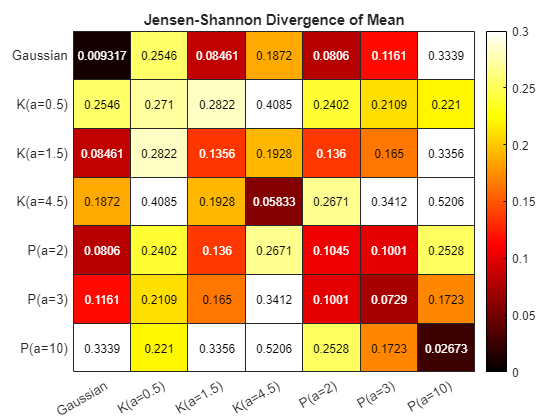

%Plot and format heat map for ML matching List
figure(1)
h=heatmap(JS_mean);
h.XData={'Gaussian','K(a=0.5)','K(a=1.5)','K(a=4.5)','P(a=2)','P(a=3)','P(a=10)'};
h.YData={'Gaussian','K(a=0.5)','K(a=1.5)','K(a=4.5)','P(a=2)','P(a=3)','P(a=10)'};
h.Colormap = hot;
h.ColorLimits=[0 0.3];
h.Title = 'Jensen-Shannon Divergence of Mean';

% build a partameter sweep of K values and perform Jensen-Shannon Divergence
%calculation and supply mean and std matricies.
K_list = cell(1,12);
K_list{1} = gauss_hist./train_samples;
for i=1:11
    K_list{i+1}=histc(ClutterSimNG('K',data_num,1, sample_len*train_samples, rho, 0.5+i, b),range,2)./train_samples;
end
[JS_Kmean,JS_Kstd] = JS_matrix(K_list)

JS_Kmean =     0.0093    0.1507    0.1170    0.1128    0.1182    0.1261    0.1377    0.1471    0.1545    0.1632    0.1704    0.1783
    0.1507    0.0475    0.0493    0.0582    0.0672    0.0766    0.0865    0.0937    0.0994    0.1053    0.1104    0.1158
    0.1170    0.0493    0.0357    0.0356    0.0396    0.0457    0.0524    0.0582    0.0631    0.0685    0.0730    0.0780
    0.1128    0.0582    0.0356    0.0296    0.0295    0.0324    0.0362    0.0409    0.0441    0.0487    0.0526    0.0569
    0.1182    0.0672    0.0396    0.0295    0.0253    0.0261    0.0274    0.0307    0.0332    0.0366    0.0396    0.0431
    0.1261    0.0766    0.0457    0.0324    0.0261    0.0245    0.0251    0.0262    0.0281    0.0307    0.0330    0.0359
    0.1377    0.0865    0.0524    0.0362    0.0274    0.0251    0.0230    0.0231    0.0240    0.0252    0.0270    0.0292
    0.1471    0.0937    0.0582    0.0409    0.0307    0.0262    0.0231    0.0227    0.0224    0.0231    0.0237    0.0250
    0.1545    0.0994 

JS_Kstd =     0.0040    0.0839    0.0406    0.0271    0.0261    0.0293    0.0300    0.0297    0.0288    0.0293    0.0285    0.0273
    0.0839    0.0480    0.0497    0.0540    0.0574    0.0598    0.0615    0.0619    0.0631    0.0622    0.0631    0.0615
    0.0406    0.0497    0.0328    0.0310    0.0341    0.0374    0.0412    0.0416    0.0433    0.0438    0.0458    0.0456
    0.0271    0.0540    0.0310    0.0246    0.0233    0.0262    0.0276    0.0295    0.0302    0.0333    0.0334    0.0344
    0.0261    0.0574    0.0341    0.0233    0.0175    0.0172    0.0191    0.0210    0.0227    0.0242    0.0250    0.0262
    0.0293    0.0598    0.0374    0.0262    0.0172    0.0159    0.0160    0.0161    0.0181    0.0199    0.0203    0.0213
    0.0300    0.0615    0.0412    0.0276    0.0191    0.0160    0.0134    0.0135    0.0138    0.0152    0.0154    0.0174
    0.0297    0.0619    0.0416    0.0295    0.0210    0.0161    0.0135    0.0123    0.0121    0.0124    0.0128    0.0139
    0.0288    0.0631  

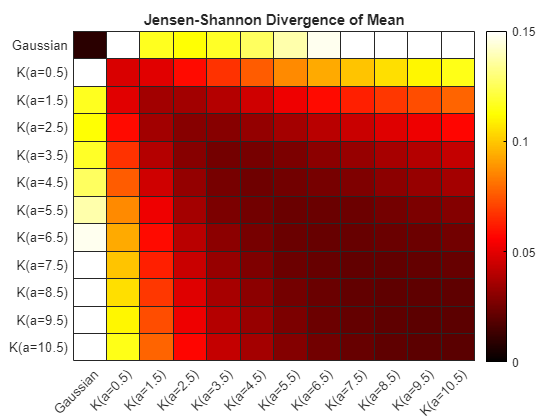

%Plot and format heat map for K dist sweep
figure(2)
h=heatmap(JS_Kmean);
h.XData={'Gaussian','K(a=0.5)','K(a=1.5)','K(a=2.5)','K(a=3.5)','K(a=4.5)','K(a=5.5)','K(a=6.5)','K(a=7.5)','K(a=8.5)','K(a=9.5)','K(a=10.5)'};
h.YData={'Gaussian','K(a=0.5)','K(a=1.5)','K(a=2.5)','K(a=3.5)','K(a=4.5)','K(a=5.5)','K(a=6.5)','K(a=7.5)','K(a=8.5)','K(a=9.5)','K(a=10.5)'};
h.Colormap = hot;
h.ColorLimits=[0 0.15];
h.Title = 'Jensen-Shannon Divergence of Mean';

% build a partameter sweep of Pareto distribution and perform Jensen-Shannon Divergence
%calculation and supply mean and std matricies.
P_list = cell(1,11);
P_list{1} = gauss_hist./train_samples;
for i=1:10
    P_list{i+1}=histc(ClutterSimNG('pareto1',data_num,1, sample_len*train_samples, rho, i, b),range,2)./train_samples;
end
[JS_Pmean,JS_Pstd] = JS_matrix(P_list)

JS_Pmean =     0.0091    0.1505    0.1865    0.2319    0.2662    0.2952    0.3212    0.3419    0.3617    0.3762    0.3908
    0.1505    0.0626    0.0638    0.0782    0.0910    0.1027    0.1140    0.1247    0.1343    0.1419    0.1501
    0.1865    0.0638    0.0386    0.0373    0.0437    0.0507    0.0589    0.0672    0.0756    0.0821    0.0900
    0.2319    0.0782    0.0373    0.0269    0.0266    0.0295    0.0340    0.0407    0.0468    0.0526    0.0590
    0.2662    0.0910    0.0437    0.0266    0.0227    0.0232    0.0254    0.0300    0.0338    0.0380    0.0439
    0.2952    0.1027    0.0507    0.0295    0.0232    0.0193    0.0194    0.0220    0.0246    0.0276    0.0327
    0.3212    0.1140    0.0589    0.0340    0.0254    0.0194    0.0178    0.0179    0.0187    0.0207    0.0243
    0.3419    0.1247    0.0672    0.0407    0.0300    0.0220    0.0179    0.0172    0.0162    0.0175    0.0196
    0.3617    0.1343    0.0756    0.0468    0.0338    0.0246    0.0187    0.0162    0.0142    0.0142 

JS_Pstd =     0.0038    0.0603    0.0723    0.0711    0.0700    0.0639    0.0579    0.0558    0.0499    0.0467    0.0469
    0.0603    0.0544    0.0582    0.0667    0.0700    0.0717    0.0726    0.0757    0.0752    0.0756    0.0759
    0.0723    0.0582    0.0387    0.0389    0.0442    0.0475    0.0507    0.0525    0.0557    0.0568    0.0589
    0.0711    0.0667    0.0389    0.0267    0.0268    0.0290    0.0326    0.0358    0.0386    0.0410    0.0431
    0.0700    0.0700    0.0442    0.0268    0.0225    0.0233    0.0266    0.0288    0.0305    0.0330    0.0356
    0.0639    0.0717    0.0475    0.0290    0.0233    0.0188    0.0194    0.0218    0.0240    0.0256    0.0281
    0.0579    0.0726    0.0507    0.0326    0.0266    0.0194    0.0167    0.0175    0.0182    0.0200    0.0224
    0.0558    0.0757    0.0525    0.0358    0.0288    0.0218    0.0175    0.0168    0.0151    0.0170    0.0196
    0.0499    0.0752    0.0557    0.0386    0.0305    0.0240    0.0182    0.0151    0.0131    0.0130  

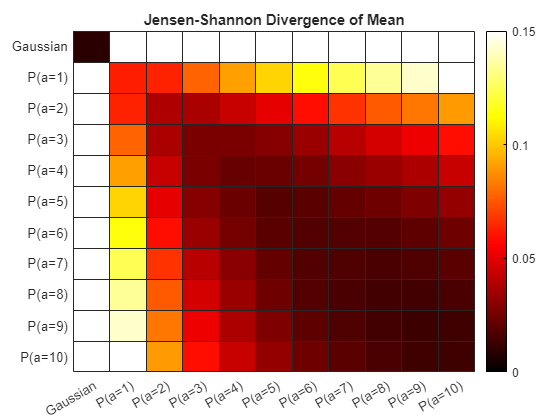

%Plot and format heat map for Pareto dist sweep (Note open in figure window
%to see values in boxes)
figure(3)
h=heatmap(JS_Pmean);
h.XData={'Gaussian','P(a=1)','P(a=2)','P(a=3)','P(a=4)','P(a=5)','P(a=6)','P(a=7)','P(a=8)','P(a=9)','P(a=10)'};
h.YData={'Gaussian','P(a=1)','P(a=2)','P(a=3)','P(a=4)','P(a=5)','P(a=6)','P(a=7)','P(a=8)','P(a=9)','P(a=10)'};
h.Colormap = hot;
h.ColorLimits=[0 0.15];
h.Title = 'Jensen-Shannon Divergence of Mean';

%Build a list of K and Pareto sweeps for one large perform Jensen-Shannon Divergence
%calculation and supply mean and std matricies.
Full_list = cell(1,22);
Full_list{1} = gauss_hist./train_samples;
for i=1:11
    Full_list{i+1}=histc(ClutterSimNG('K',data_num,1, sample_len*train_samples, rho, 0.5+i, b),range,2)./train_samples;
end
for i=1:10
    Full_list{i+12}=histc(ClutterSimNG('pareto1',data_num,1, sample_len*train_samples, rho, i, b),range,2)./train_samples;
end
[JS_Fmean,JS_Fstd] = JS_matrix(Full_list)

JS_Fmean =     0.0091    0.1519    0.1140    0.1118    0.1181    0.1267    0.1373    0.1463    0.1546    0.1638    0.1704    0.1767    0.1491    0.1797    0.2298    0.2691    0.2976    0.3226    0.3428    0.3600    0.3774    0.3902
    0.1519    0.0500    0.0489    0.0588    0.0681    0.0777    0.0869    0.0938    0.1004    0.1070    0.1116    0.1164    0.0569    0.0489    0.0579    0.0705    0.0812    0.0918    0.1007    0.1088    0.1177    0.1244
    0.1140    0.0489    0.0328    0.0335    0.0379    0.0446    0.0507    0.0565    0.0612    0.0673    0.0716    0.0757    0.0487    0.0593    0.0810    0.0998    0.1147    0.1274    0.1383    0.1480    0.1577    0.1654
    0.1118    0.0588    0.0335    0.0279    0.0293    0.0312    0.0352    0.0390    0.0433    0.0477    0.0514    0.0547    0.0545    0.0752    0.1020    0.1226    0.1381    0.1515    0.1629    0.1728    0.1825    0.1900
    0.1181    0.0681    0.0379    0.0293    0.0259    0.0269    0.0280    0.0307    0.0335    0.0369    0

JS_Fstd =     0.0040    0.0869    0.0357    0.0263    0.0267    0.0289    0.0293    0.0292    0.0293    0.0289    0.0277    0.0272    0.0585    0.0696    0.0740    0.0678    0.0633    0.0591    0.0560    0.0526    0.0471    0.0450
    0.0869    0.0544    0.0500    0.0560    0.0594    0.0625    0.0630    0.0646    0.0646    0.0645    0.0655    0.0653    0.0565    0.0455    0.0473    0.0511    0.0542    0.0586    0.0606    0.0608    0.0628    0.0628
    0.0357    0.0500    0.0287    0.0293    0.0314    0.0360    0.0376    0.0400    0.0404    0.0415    0.0425    0.0432    0.0414    0.0452    0.0512    0.0530    0.0551    0.0549    0.0550    0.0545    0.0546    0.0541
    0.0263    0.0560    0.0293    0.0226    0.0224    0.0239    0.0265    0.0282    0.0306    0.0315    0.0331    0.0329    0.0425    0.0494    0.0527    0.0513    0.0514    0.0508    0.0501    0.0499    0.0486    0.0482
    0.0267    0.0594    0.0314    0.0224    0.0183    0.0179    0.0196    0.0207    0.0225    0.0242    0.

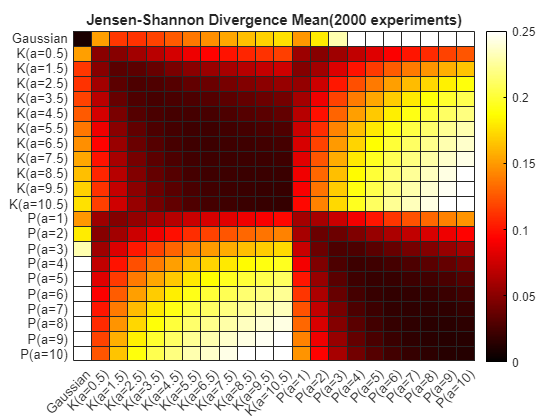

%Plot and format heat map for Gaussian, K sweep, and Pareto dist sweep
figure(4)
h=heatmap(JS_Fmean);
h.XData={'Gaussian','K(a=0.5)','K(a=1.5)','K(a=2.5)','K(a=3.5)','K(a=4.5)','K(a=5.5)',...
    'K(a=6.5)','K(a=7.5)','K(a=8.5)','K(a=9.5)','K(a=10.5)','P(a=1)','P(a=2)','P(a=3)',...
    'P(a=4)','P(a=5)','P(a=6)','P(a=7)','P(a=8)','P(a=9)','P(a=10)'};
h.YData={'Gaussian','K(a=0.5)','K(a=1.5)','K(a=2.5)','K(a=3.5)','K(a=4.5)','K(a=5.5)',...
    'K(a=6.5)','K(a=7.5)','K(a=8.5)','K(a=9.5)','K(a=10.5)','P(a=1)','P(a=2)','P(a=3)',...
    'P(a=4)','P(a=5)','P(a=6)','P(a=7)','P(a=8)','P(a=9)','P(a=10)'};
h.Colormap = hot;
h.ColorLimits=[0 0.25];
h.Title = 'Jensen-Shannon Divergence Mean(2000 experiments)';

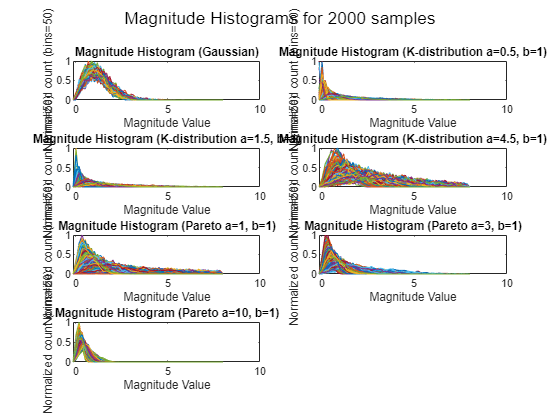

%Format and plot the stacked histograms for the selection for the ML core
%inputs.  
figure(5)
subplot(4,2,1)
sgtitle('Magnitude Histograms for 2000 samples')
plot(range,(gauss_hist./max(max(gauss_hist)))')
title('Magnitude Histogram (Gaussian)')
xlabel('Magnitude Value') 
ylabel('Normalized count (bins=50)')
subplot(4,2,2)
plot(range,(K0_5_hist./max(max(K0_5_hist)))')
title('Magnitude Histogram (K-distribution a=0.5, b=1)')
xlabel('Magnitude Value') 
ylabel('Normalized count (bins=50)')
subplot(4,2,3)
plot(range,(K1_5_hist./max(max(K1_5_hist)))')
title('Magnitude Histogram (K-distribution a=1.5, b=1)')
xlabel('Magnitude Value') 
ylabel('Normalized count (bins=50)')
subplot(4,2,4)
plot(range,(K4_5_hist./max(max(K4_5_hist)))')
title('Magnitude Histogram (K-distribution a=4.5, b=1)')
xlabel('Magnitude Value') 
ylabel('Normalized count (bins=50)')
subplot(4,2,5)
plot(range,(P1_hist./max(max(P1_hist)))')
title('Magnitude Histogram (Pareto a=1, b=1)')
xlabel('Magnitude Value') 
ylabel('Normalized count (bins=50)')
subplot(4,2,6)
plot(range,(P3_hist./max(max(P3_hist)))')
title('Magnitude Histogram (Pareto a=3, b=1)')
xlabel('Magnitude Value') 
ylabel('Normalized count (bins=50)')
subplot(4,2,7)
plot(range,(P10_hist./max(max(P10_hist)))')
title('Magnitude Histogram (Pareto a=10, b=1)')
xlabel('Magnitude Value') 
ylabel('Normalized count (bins=50)')

% Given the number of classes, generate the labels for the ML training
classes=7;                                                                  % Number of classes
label=zeros(data_num*classes,1);                                            % Set-up label variable and incrememnt for classes
for i=2:classes
    label(data_num*(i-1)+1:data_num*i,1) = (i-1);
end

data = cat(1,gauss_out,K0_5_out,K1_5_out,K4_5_out,P2_out,P3_out,P10_out);   % Build data variable from generated data (see above)
save('clutter_order_7b.mat','data', 'label')                                % Generate .mat file to import to python for ML training                           


function [rank_x] = order_stats(x,k)                    % Ordered statistics function.  
[n1,n2]=size(x);                                        % Determine input size
sort_x = sort(x,2);                                     % Sort each sample          
rank_x = zeros(n1,k);                                   % Build rank matrix
span=(n2-1)/(k-1);                                      % Calculate the index span for internal ordered values
spans = 0:1:(k-1);                                      % develop the indexes for ordered stats
set_span = int64(spans*span+1);                         % truncate to integers for ordered stats index
for i=1:k                                               % loop all indexes to build ordered statictics
    rank_x(:,i)=sort_x(:,set_span(i));
end
end

function [Dkl_PQ] = KBLV(P,Q)                           % Kullback Leiber function (expects normalized histograms)
Dkl_PQ=zeros(size(P,1),1);                              % Build empty vector for each sample
P=P+eps;                                                % Ensure no divide by 0 error
Q=Q+eps;                                                % Ensure no divide by 0 error                                            
for i=1:size(P,2)
    Dkl_PQ = Dkl_PQ+ P(:,i).*log(P(:,i)./Q(:,i));       % Calculate Prob(P)*ln (Prob(P)/Prob(Q))
end
end

function [JS] = JenShan(P,Q)                            % Jensen-Shannon Divergence Function
M = .5.*(P+Q);                                          % Calculate M
JS = .5.*KBLV(P,M)+.5.*KBLV(Q,M);                       % Generate symetrical divergence given P and Q
end

function [JS_mean,JS_std]= JS_matrix(dist_list)         % Build the matrix of JS mean and STD given a dictionary of histograms
JS_mean = zeros(size(dist_list,2),size(dist_list,2));   % Build empty mean matrix
JS_std = zeros(size(dist_list,2),size(dist_list,2));    % Build empty std matrix
for i=1:size(dist_list,2)                               % loop list twice (all combinations)
    for j = 1:size(dist_list,2)
        if i==j                                         % for diagonal, shuffle the samples so it is not directly score of 0.
            temp_dist = dist_list{i};
            rand_dist = temp_dist(randperm(size(temp_dist, 1)), :); % shuffle samples.
            JS_mean(i,j) = mean(JenShan(dist_list{i},rand_dist));   % Calculate diagonal mean
            JS_std(i,j) = std(JenShan(dist_list{i},rand_dist));     % Calculate diagonal std
        else
            JS_mean(i,j) = mean(JenShan(dist_list{i},dist_list{j}));% Calculate non-diagonal mean
            JS_std(i,j) = std(JenShan(dist_list{i},dist_list{j}));  % Calculate non-diagonal std
        end
    end
end
end